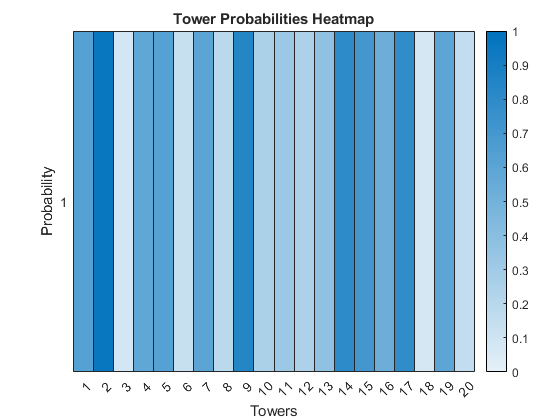

% Define the parameters
clc; clear;
numAnts = 10;
numIterations = 10;
alpha = 1;   % Pheromone importance
beta = 3;    % Prob importance
evaporationRate = 0.8;

% Generate random tower positions and probabilities
numTowers = 20;
towerProbabilities = rand(numTowers, 1);

% Reshape the array for heatmap
heatmapData = reshape(towerProbabilities, 1, []);

% Plot the heatmap
figure;
heatmap(heatmapData, 'ColorLimits', [0, 1], ...
    'XLabel', 'Towers', 'YLabel', 'Probability', 'Title', 'Tower Probabilities Heatmap');

Iteration 1: Min Average Probability = 0.4513


CPU Time: 0.0000 seconds


GPU Time: 0.0000 seconds


Total Runtime: 2.3316 seconds



Iteration 2: Min Average Probability = 0.4390


CPU Time: 0.0000 seconds


GPU Time: 0.0000 seconds


Total Runtime: 2.1658 seconds



Iteration 3: Min Average Probability = 0.4390


CPU Time: 0.0000 seconds


GPU Time: 0.0000 seconds


Total Runtime: 2.1354 seconds



Iteration 4: Min Average Probability = 0.4390


CPU Time: 0.0000 seconds


GPU Time: 0.0000 seconds


Total Runtime: 2.1139 seconds



Iteration 5: Min Average Probability = 0.4390


CPU Time: 0.0000 seconds


GPU Time: 0.0000 seconds


Total Runtime: 2.1179 seconds



Iteration 6: Min Average Probability = 0.4390


CPU Time: 0.0000 seconds


GPU Time: 0.0000 seconds


Total Runtime: 2.1340 seconds



Iteration 7: Min Average Probability = 0.4390


CPU Time: 0.0000 seconds


GPU Time: 0.0000 seconds


Total Runtime: 2.1178 seconds



Iteration 8: Min Average Probability = 0.4390


CPU Time: 0.0000 seconds


GPU Time: 0.0000 seconds


Total Runtime: 2.1131 seconds



Iteration 9: Min Average Probability = 0.4390


CPU Time: 0.0000 seconds


GPU Time: 0.0000 seconds


Total Runtime: 2.1195 seconds



Iteration 10: Min Average Probability = 0.4390


CPU Time: 0.0000 seconds


GPU Time: 0.0000 seconds


Total Runtime: 2.1296 seconds



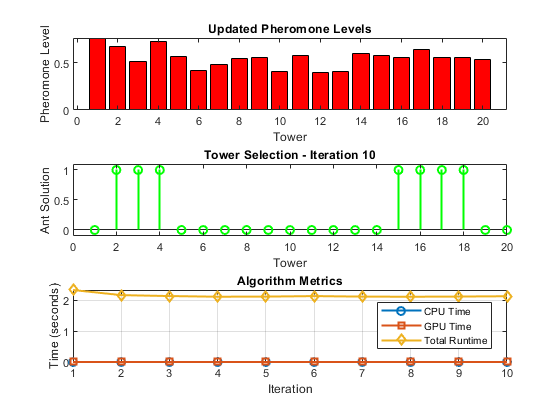


% Define problem-specific parameters
k = 8;    % Number of TLAs to install
minConsecutiveTLAs = 3;

% Initialize pheromone levels
pheromoneLevels = ones(numTowers, 1);

% Initialize the best solution and its probability
bestSolution = [];
minAvgProbability = 1;

% Initialize metrics arrays
cpuTime = zeros(numIterations, 1);
gpuTime = zeros(numIterations, 1);
runtimes = zeros(numIterations, 1);

for iteration = 1:numIterations
    tic;
    antSolutions = cell(numAnts, 1); % Empty array
    antProbabilities = zeros(numAnts, 1);

    for ant = 1:numAnts
        visited = false(numTowers, 1); % Logical zeros
        antSolution = zeros(k, 1); % TLAs install index, black = 1, white = 0

        % Construct the solution
        for tower = 1:numTowers
            % Calculate probabilities for unvisited towers using pheromones
            unvisitedIndices = find(~visited);
            probabilities = (pheromoneLevels(unvisitedIndices) .^ alpha) .* (towerProbabilities(unvisitedIndices) .^ beta);
            probabilities = probabilities / sum(probabilities);

            % Choose tower with pheromone-based probability
            chosenTower = chooseWithProbability(probabilities, pheromoneLevels, alpha, beta);

            if ~isempty(chosenTower)
                % Update the antSolution and visited array
                antSolution = installTLAs(chosenTower, antSolution, k, minConsecutiveTLAs);
                visited(chosenTower) = true;
            end
        end

        antSolutions{ant} = antSolution;
        antProbabilities(ant) = mean(towerProbabilities(antSolution(antSolution <= numTowers)));
    end

    % Update pheromone levels based on the best ant solution
    [~, bestAnt] = min(antProbabilities);
    bestAntSolution = antSolutions{bestAnt};
    
    for i = 1:numel(bestAntSolution) - minConsecutiveTLAs + 1
        subSolution = bestAntSolution(i:i + minConsecutiveTLAs - 1);
        if max(subSolution) <= numel(pheromoneLevels)
            avgProbability = mean(towerProbabilities(subSolution));
            pheromoneLevels(subSolution) = (1 - evaporationRate) * pheromoneLevels(subSolution) + avgProbability;
        end
    end

    % Update the best solution if a better one is found
    if antProbabilities(bestAnt) < minAvgProbability
        bestSolution = bestAntSolution;
        minAvgProbability = antProbabilities(bestAnt);
    end

    % Display the best solution in this iteration
    % fprintf('Iteration %d: Min Average Probability = %.4f\n', iteration, minAvgProbability);

    % Plot the updated pheromone levels
    subplot(3, 1, 1);
    bar(1:numTowers, pheromoneLevels, 'r');
    title('Updated Pheromone Levels');
    xlabel('Tower');
    ylabel('Pheromone Level');

    % Pause for visualization (adjust as needed)
    pause(1);
    
    % Plot the tower selection for the best ant
    subplot(3, 1, 2);
    plotAntSolution(bestAntSolution, numTowers);
    title(['Tower Selection - Iteration ' num2str(iteration)]);
    xlabel('Tower');
    ylabel('Ant Solution');

    % Pause for visualization (adjust as needed)
    pause(1);
    
    % Measure runtime
    runtimes(iteration) = toc;

    % Display the best solution in this iteration
    fprintf('Iteration %d: Min Average Probability = %.4f\n', iteration, minAvgProbability);
    fprintf('CPU Time: %.4f seconds\n', cpuTime(iteration));
    fprintf('GPU Time: %.4f seconds\n', gpuTime(iteration));
    fprintf('Total Runtime: %.4f seconds\n\n', runtimes(iteration));

    % Plot metrics
    subplot(3, 1, 3);
    plotMetrics(cpuTime, gpuTime, runtimes, iteration);
end



% Display the final best solution and its average probability
fprintf('Final Best Solution:\n');

Final Best Solution:


fprintf('Average Probability = %.4f\n', minAvgProbability);

Average Probability = 0.4390


fprintf('TLA Positions = %s\n', mat2str(sort(bestSolution)));

TLA Positions = [2;3;4;8;9;10;12;13]



% Calculate total runtime
totalRuntime = toc(totalRuntime);

Unrecognized function or variable 'totalRuntime'.


% Display metrics
fprintf('Convergence Speed:\n');
disp(convergenceSpeed);

fprintf('Best Solution Qualities:\n');
disp(bestSolutionQualities);

fprintf('Diversity of Solutions:\n');
disp(diversityOfSolutions);

fprintf('Total Runtime: %.4f seconds\n', totalRuntime);

function antSolution = installTLAs(tower, antSolution, k, minConsecutiveTLAs)
    not_installed = find(~antSolution);
    sumNonZero = sum(antSolution ~= 0);
    k_remain = k - sumNonZero;

    if k_remain >= minConsecutiveTLAs
        % Find consecutive available positions to install minConsecutiveTLAs TLAs
        consecutive_spaces = find(diff(not_installed) == 1);
        start_idx = 1;
        for i = 1:length(consecutive_spaces)
            if consecutive_spaces(i) >= minConsecutiveTLAs - 1
                start_idx = consecutive_spaces(i) - minConsecutiveTLAs + 2;
                break;
            end
        end

        end_idx = start_idx + minConsecutiveTLAs - 1;
        if end_idx > length(not_installed)
            end_idx = length(not_installed);
        end

        % Check for redundancy and adjust if necessary
        while any(ismember(antSolution(not_installed(start_idx:end_idx)), antSolution(antSolution ~= 0)))
            % If redundancy is found, shift the installation by one position
            start_idx = start_idx + 1;
            end_idx = start_idx + minConsecutiveTLAs - 1;
            if end_idx > length(not_installed)
                end_idx = length(not_installed);
            end
        end

        antSolution(not_installed(start_idx:end_idx)) = tower + (0:(end_idx - start_idx));
    else
        if k_remain > 0
            % If not enough space for minConsecutiveTLAs, install as many as possible
            minConsecutiveTLAs = k_remain;
%             fprintf('Warning: Not enough space for %d consecutive TLAs. Installed %d TLAs instead.\n', k, minConsecutiveTLAs);
        else
%             fprintf('Error: Not enough available positions to install %d TLAs.\n', k);
            return; % Return without modifying antSolution
        end
        % Update to handle the case when minConsecutiveTLAs > length(not_installed)
        end_idx = min(minConsecutiveTLAs, length(not_installed));
        antSolution(not_installed(1:end_idx)) = tower + (0:(end_idx - 1));
    end
end

function choice = chooseWithProbability(probabilities, pheromones, pheromoneImportance, beta)
    % Calculate probabilities for unvisited towers
    unvisitedIndices = find(probabilities > 0);
    probabilities = (pheromones(unvisitedIndices) .^ pheromoneImportance) .* (probabilities(unvisitedIndices) .^ beta);
    probabilities = probabilities / sum(probabilities);

    cumulativeProbabilities = cumsum(probabilities);
    if ~isempty(cumulativeProbabilities)
        randValue = rand() * cumulativeProbabilities(end);
        choice = unvisitedIndices(find(randValue <= cumulativeProbabilities, 1, 'first'));
    else
        % Handle the case when cumulativeProbabilities is empty
        choice = [];
    end
end


% Function to plot the tower selection for an ant solution
function plotAntSolution(antSolution, numTowers)
    antPlot = zeros(1, numTowers);
    indices = antSolution(antSolution ~= 0);
    antPlot(indices) = 1;
    stem(1:numTowers, antPlot, 'g', 'LineWidth', 1.5);
    ylim([-0.1, 1.1]);
end

function diversity = calculateDiversity(solutions)
    % Calculate diversity of solutions based on some criterion
    % This is a placeholder; you might need to define a suitable diversity metric
    % based on your specific problem.
    % Here, I'm simply counting the unique solutions.
    uniqueSolutions = unique(cell2mat(solutions), 'rows');
    diversity = size(uniqueSolutions, 1);
end

function plotMetrics(cpuTime, gpuTime, runtimes, iteration)
    plot(1:iteration, cpuTime(1:iteration), '-o', 'LineWidth', 1.5, 'DisplayName', 'CPU Time');
    hold on;
    plot(1:iteration, gpuTime(1:iteration), '-s', 'LineWidth', 1.5, 'DisplayName', 'GPU Time');
    plot(1:iteration, runtimes(1:iteration), '-d', 'LineWidth', 1.5, 'DisplayName', 'Total Runtime');
    hold off;
    title('Algorithm Metrics');
    xlabel('Iteration');
    ylabel('Time (seconds)');
    legend('Location', 'Best');
    grid on;
    drawnow;
end